L = 0.127

L = 0.1270



v_a1 = -180:0.5:180;
v_a2 = 0:0.5:360;

a1_adm = [];
a2_adm = [];
p1_adm = [];

a1_err = [];
a2_err = [];
p1_err = [];

a1_imp = [];
a2_imp = [];
p1_imp = [];
for i = 1:size(v_a1,2)
    for j = 1:size(v_a2,2)
        a1 = deg2rad(v_a1(i));
        a2 = deg2rad(v_a2(j));
        
        [x, y, p1 , p2, error] = direct_kinematics(a1,a2);
        a2 = a2-pi/2;
        if error == 0
            a1_adm(end+1) = a1;
            a2_adm(end+1) = a2;
            p1_adm(end+1) = p1;
        elseif not(isnan(p1))
            a1_err(end+1) = a1;
            a2_err(end+1) = a2;
            p1_err(end+1) = p1;
        else
            a1_imp(end+1) = a1;
            a2_imp(end+1) = a2;
            p1_imp(end+1) = -1;
        end

    end
end


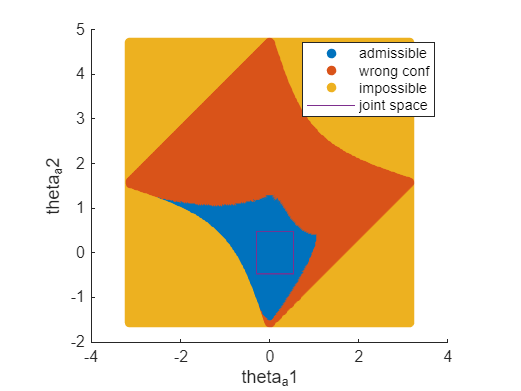


figure
hold on
scatter3(a1_adm,a2_adm,p1_adm,'filled')
scatter3(a1_err,a2_err,p1_err,"filled")
scatter3(a1_imp,a2_imp,p1_imp,"filled")
plot3( deg2rad([-17 31 31 -17 -17]), deg2rad([-27 -27 27 27 -27]), [10 10 10 10 10] )

xlabel("theta_a1")
ylabel("theta_a2")
rectangle('Position',deg2rad([-17 -27 31 27]))
legend(["admissible","wrong conf","impossible","joint space"])
daspect([1 1 0.1])
hold off